## Import Data

clear all;
clc;
data = readtable("BuckPIDStep30to5_100khz.csv");
data = fillmissing(data,'nearest')

data = 2002×3 table
       Var1           Var2             Var3    
    __________    _____________    ____________

      -1.2e-05                1               4
      -1.2e-05                1               4
      -1.2e-05    -0.0275753923    0.4515829124
    -1.175e-05    -0.0275753923    0.4515829124
     -1.15e-05    -0.0275753923    0.4515829124
    -1.125e-05    -0.0112437342    0.4515829124
      -1.1e-05    -0.0212939853    0.4515829124
    -1.075e-05    -0.0275753923    0.4508291435
     -1.05e-05    -0.0275753923    0.4435427114
    -1.025e-05    -0.0037060458    0.4324874352
        -1e-05    -0.0150125783      0.44228643
     -9.75e-06    -0.0275753923    0.4508291435
      -9.5e-06    -0.0137562969    0.4435427114
     -9.25e-06    -0.0275753923    0.4468090431
        -9e-06    -0.0212939853    0.4447989928
     -8.75e-06     0.0088567681    0.4515829124


data([1,2],:) = [];

## Assign Variables

% Seperate values
t = table2array(data(:,1))+1.2e-5;
ADC = round(table2array(data(:,3))/5*1024)

ADC =     92
    92
    92
    92
    92
    92
    91
    89
    91
    92


OCR = table2array(data(:,2));
% Match to duty cycle
OCR = 30-round(OCR/5)*25

OCR =     30
    30
    30
    30
    30
    30
    30
    30
    30
    30



% Find index before step
idx = find(OCR>10,1,'last')

idx =     49



% Trim data with new index
t = t(idx-5:end);
ADC = ADC(idx-5:end);
OCR = OCR(idx-5:end);

% Reset time and find sampling time
t = t-t(1);
T_s=t(2)-t(1)

T_s =      2.499999999999993e-07


## Plot Real Data

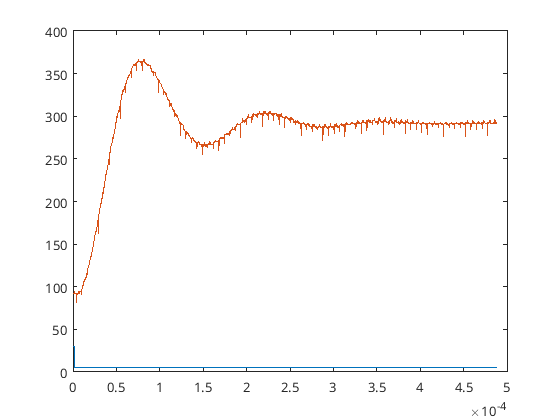

clf;
plot(t,OCR)
hold on
plot(t,ADC)
hold off

clf

## Identify Transfer Functions

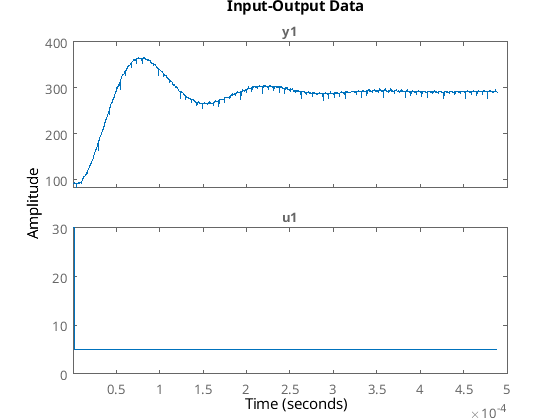

idd = iddata(ADC,OCR,T_s);
plot(idd)

G=tfest(idd,2,0)

G =
 
  From input "u1" to output "y1":
           9.908e10
  ---------------------------
  s^2 + 2.667e04 s + 1.703e09
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                         
Estimated using TFEST on time domain data "idd".
Fit to estimation data: 89.24%                  
FPE: 27.74, MSE: 27.6                           


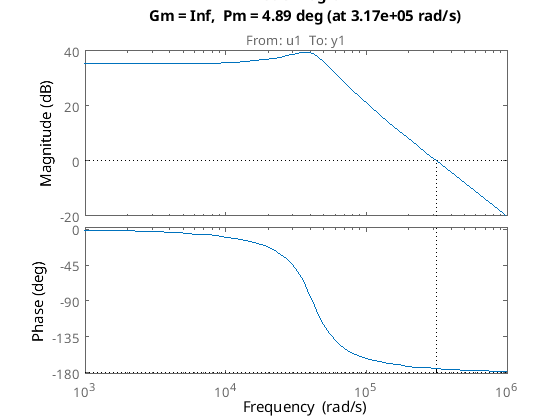

margin(G)

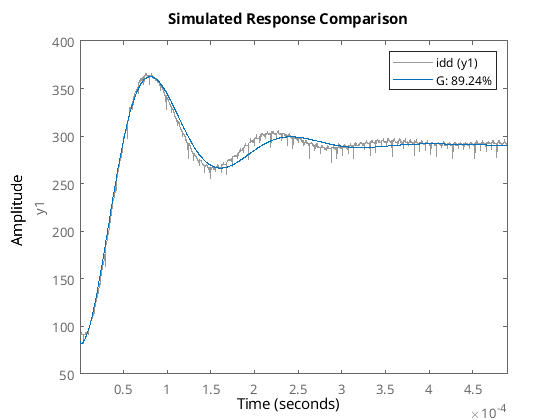

compare(idd,G)

## Create PID Controller

format long
abs(pole(G))

ans = 1.0e+04 *

   4.126459031470028
   4.126459031470028


gm = 60; Ni=3; alpha=0.2;
[wc, Kp, taui,taud, ok] = findpid(G, gm, Ni,alpha)

ans = 'Found 1 valid solution(s) out of 1 phase crossing(s)'

wc =      6.308665726484720e+04


Kp =    0.012123994348870


taui =      4.755363701401316e-05


taud =      3.544438831356118e-05


ok =      1


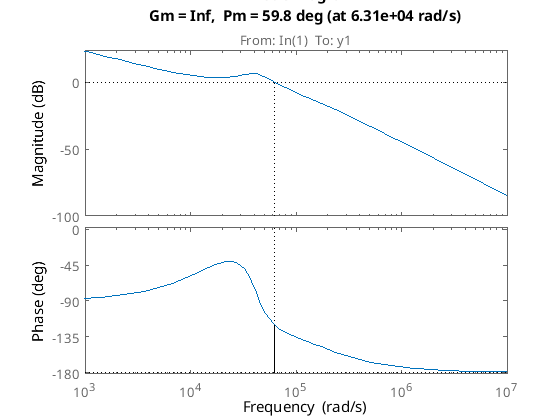

s=tf('s');
Cpid=minreal(Kp*(taui*s+1)/(taui*s)*(taud*s+1)/(alpha*taud*s+1));
Gol=minreal(G*Cpid);
Gcl=minreal(Gol/(1+Gol));
margin(Gol);

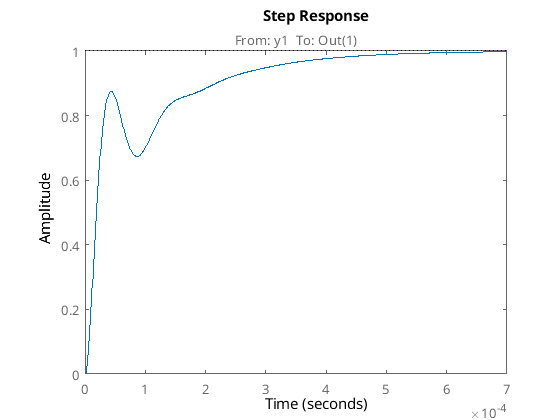

step(1*Gcl);

## Z-Transform and Output

format long
Gz=c2d(Cpid,1/10e3,'tustin');
Gz.Variable= 'z^-1'

Gz =
 
  0.03723 + 0.007275 z^-1 + 0.000159 z^-2
  ---------------------------------------
       1 - 0.2483 z^-1 - 0.7517 z^-2
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



[num, den] = tfdata(Gz, 'v')

num =    0.037225238789948   0.007274890487572   0.000159023694856


den =    1.000000000000000  -0.248345315337750  -0.751654684662250



format long
% Open the file for writing
fileID = fopen('../Code/Buck PID Mega/lib/Controllers/Data.h', 'w');

% Write the array declaration to the file
fprintf(fileID, 'double num[%d] = {',length(num));

% Write each element of the array to the file
for i = 1:length(num)
    fprintf(fileID, '%0.16f', num(i));
    
    % Add a comma after each element except the last one
    if i < length(num)
        fprintf(fileID, ', ');
    end
end

% Complete the array declaration
fprintf(fileID, '};\n');

% Write the array declaration to the file
fprintf(fileID, 'double den[%d] = {',length(den));

% Write each element of the array to the file
for i = 1:length(num)
    fprintf(fileID, '%0.16f', den(i));
    
    % Add a comma after each element except the last one
    if i < length(den)
        fprintf(fileID, ', ');
    end
end

% Complete the array declaration
fprintf(fileID, '};\n');

% Close the file
fclose(fileID);

